
% adding sensor at all points in a plane
% sensor.mask(:,:,:) = 1;

% % 3D sensor plots over time - vector version...
% 
% figure;
% for tt=1:length(kgrid.t_array)
%     quiver3()
% end


% testing 3d array stuff

clearvars;
% create the computational grid
xSize = 0.7;        % height of grid in meters
ySize = 0.3;        % length of grid in meters
zSize = 0.1;        % width of grid in meters
Nx = 128;           % number of grid points in the x (row) direction
Ny = 64;            % number of grid points in the y (column) direction
Nz = 32;            % number of grid points in the z (slice) direction
dx = xSize/Nx;    	% grid point spacing in the x direction [m]
dy = ySize/Ny;      % grid point spacing in the y direction [m]
dz = zSize/Nz;      % grid point spacing in the z direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy, Nz, dz);

% define sound speed in the two layers
c1 = 1500;          % water
c2 = 5100;          % aluminium

% define the properties of the propagation medium
medium.sound_speed = c1 * ones(Nx, Ny,Nz);     % [m/s]
medium.sound_speed(round(Nx/3):round(Nx/3)+5, Ny/2-3:Ny/2+3, Nz/2-3:Nz/2+3) = c2;
medium.density = 1000 * ones(Nx, Ny,Nz);       % [kg/m^3]
medium.density(round(Nx/3):round(Nx/3)+5, Ny/2-3:Ny/2+3, Nz/2-3:Nz/2+3) = 2700;

% create the time array
kgrid.makeTime(medium.sound_speed);

kgrid.Nt = 1000

kgrid =   kWaveGrid with properties:

                   Nx: 128
                   Ny: 64
                   Nz: 32
                   dx: 0.0055
                   dy: 0.0047
                   dz: 0.0031
               kx_vec: [128×1 double]
               ky_vec: [64×1 double]
               kz_vec: [32×1 double]
                    k: [128×64×32 double]
               kx_max: 574.4627
               ky_max: 670.2064
               kz_max: 1.0053e+03
                k_max: 574.4627
                  dim: 3
           nonuniform: 0
                   dt: 1.8382e-07
                   Nt: 1000
                x_vec: [128×1 double]
                y_vec: [64×1 double]
                z_vec: [32×1 double]
                    x: [128×64×32 double]
                    y: [128×64×32 double]
                    z: [128×64×32 double]
                   kx: [128×64×32 double]
                   ky: [128×64×32 double]
         


% create the time array
kgrid.makeTime(medium.sound_speed);

% using source from ewp 3D example
num_elements = 21;
x_offset = 5

x_offset = 5

y_offset = Ny/2 - round(num_elements/2) + 1

y_offset = 22

z_offset = Nz/2 - round(num_elements/2) + 1

z_offset = 6

source.p_mask = zeros(Nx, Ny, Nz);
source.p_mask(x_offset, y_offset:y_offset + num_elements - 1, z_offset:z_offset + num_elements - 1) = 1

source = struct with fields:
    p_mask: [128×64×32 double]



source_freq = 200e3;      % [Hz]
source_mag = 1e6;    % [MPa]
source_cycles = 5;
source.p = source_mag * toneBurst(1/kgrid.dt, source_freq, source_cycles);
% use envelope detection
source.p = envelopeDetection(source.p);

%define sensor mask
sensor.mask = zeros(Nx, Ny, Nz);
sensor.mask(x_offset, y_offset:y_offset + num_elements - 1, z_offset:z_offset + num_elements - 1) = 1;

sensor.mask(:,:,31)

Index in position 3 exceeds array bounds. Index must not exceed 32.

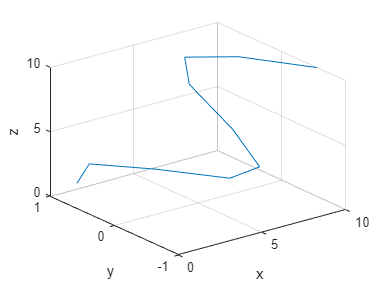

% just a 3d plot test
xxxx = 1:1:10;
yyyy = sin(xxxx);
zzzz = 1:1:10;

figure;
plot3(xxxx,yyyy,zzzz);
xlabel('x'); % time
ylabel('y'); % sensor number
zlabel('z'); % amplitude
grid on

% trying waterfall plots 2 - https://uk.mathworks.com/matlabcentral/answers/514641-how-can-i-plot-a-3d-waterfall

T = sensor_data;
kgrid.t_array

ans = 1.0e-03 *

         0    0.0005    0.0009    0.0014    0.0018    0.0023    0.0028    0.0032    0.0037    0.0041    0.0046    0.0051    0.0055    0.0060    0.0064    0.0069    0.0074    0.0078    0.0083    0.0087    0.0092    0.0097    0.0101    0.0106    0.0110    0.0115    0.0119    0.0124    0.0129    0.0133    0.0138    0.0142    0.0147    0.0152    0.0156    0.0161    0.0165    0.0170    0.0175    0.0179    0.0184    0.0188    0.0193    0.0198    0.0202    0.0207    0.0211    0.0216    0.0221    0.0225


1:size(T,2)

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


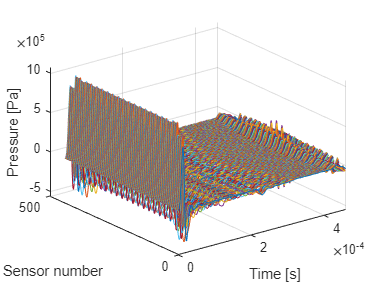


[y,x] = meshgrid(1:size(T,1), kgrid.t_array);  % T is your table
z = T(:,:); 
plot3(x,y,z);
xlabel('Time [s]'); % time
ylabel('Sensor number'); % sensor number
zlabel('Pressure [Pa]'); % amplitude
grid on


% gca().DataAspectRatio
% 
% daspect([1 35000 2000]);

% trying waterfall plots

[X,Y] = meshgrid(-3:.125:3);
Z = peaks(X,Y);
waterfall(Z)